# Métodos Numéricos y Programación

*F. Pena*

## Tema 5. Interpolación 

### Interpolación global

`El comando p = `[`polyfit`](https://es.mathworks.com/help/matlab/ref/polyfit.html)`(x,y,n) `devuelve los coeficientes de un polinomio `p(x)` de grado `n` que ajuste por mínimos mínimos cuadrados los datos de `y`. Los coeficientes de `p` se indican de mayor a menor grado, es decir $p(x) = 
p_1x^n+p_2x^{n-1}+\ldots+p_nx+p_{n+1}$. 

Si tomamos como `n` el número de puntos menos uno, estamos calculando el polinomio de interpolación global.

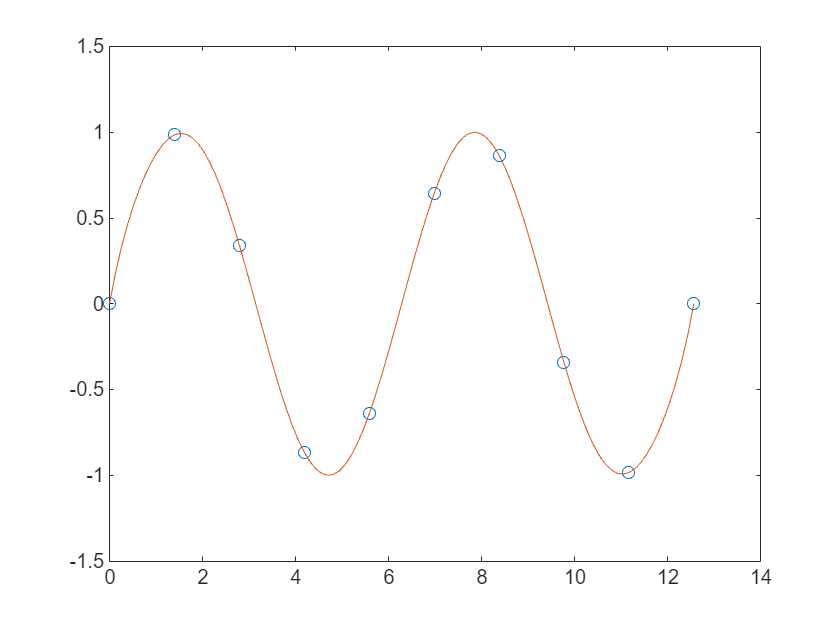

x = linspace(0, 4*pi, 10); %abscisas de los nodos de interpolacion
p = polyfit(x, sin(x), length(x)-1);
xp = linspace(0,4*pi);     %abscisas para la grafica
plot(x,sin(x),'o', xp,polyval(p,xp))

El polinomio de interpolación global sólo puede calcularse en un ordenador para un máximo de nodos `n` (que depende de cada función e intervalo) antes de que los errores numéricos se acumulen. La función `interplot` construye la gráfica:

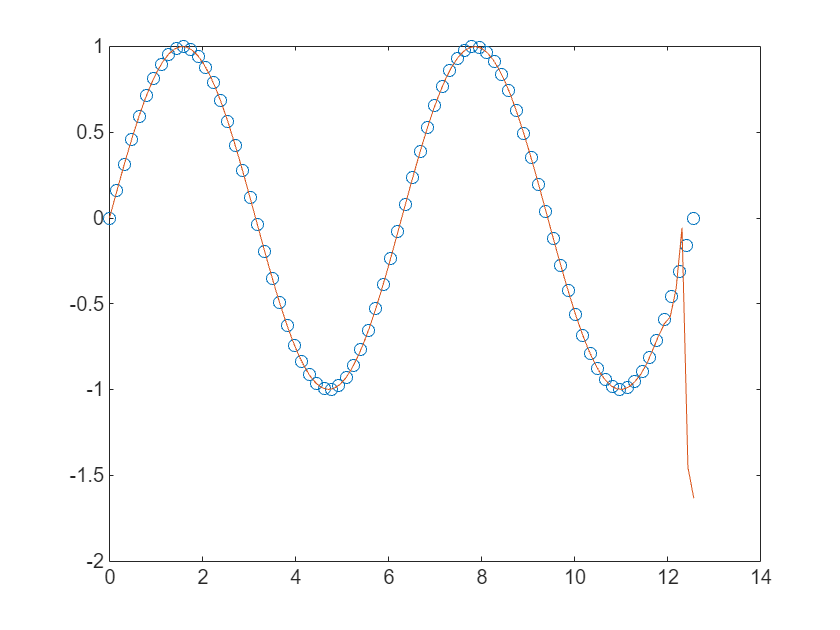

p = interplot(@(x)sin(x), 0, 4*pi, 80);

Esta acumulación se debe a que restamos monomios obtenidos de multiplicar coeficientes muy pequeños por evaluación es muy grandes. Por ejemplo, en el caso anterior, el monomio de mayor grado consiste en multiplicar.

p(1), (4*pi)^80

ans = 3.8103e-73

ans = 8.6455e+87

El fenómeno de Runge consiste en que el error máximo entre el polinomio y la función interpolada, en el intervalo de interpolación, tiene a infinito cuando `n` tiende a infinito. Por tanto, en un ordenador tenemos una ventana de oportunidad para observar la tendencia del error antes de que el cálculo del polinomio deje de tener sentido. En el caso anterior, para `n=40` aún podemos observar el polinomio:

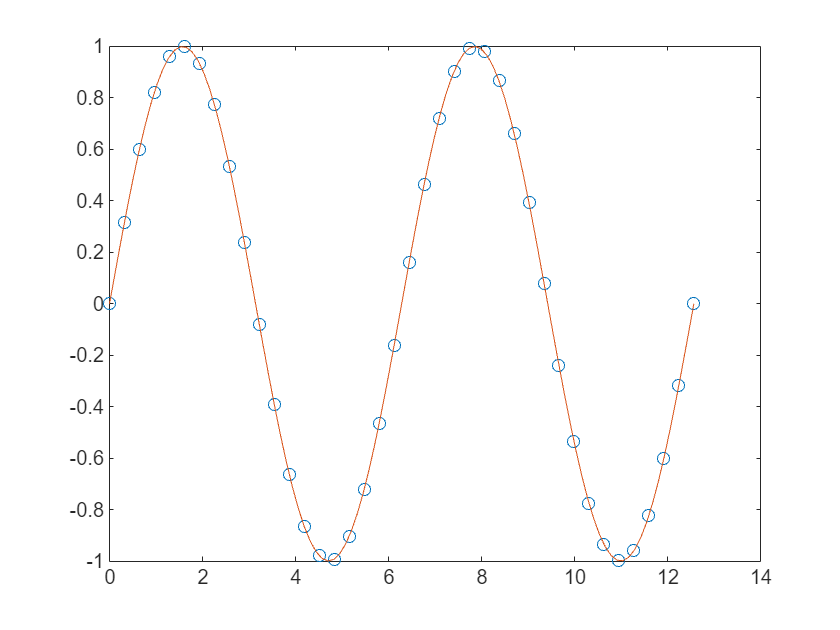

interplot(@(x)sin(x), 0, 4*pi, 40);

La función `runge` nos permite indicar un intervalo, una función y unos valores de `n` en los que observar el valor máximo (calculado en una evaluación en 100 puntos):

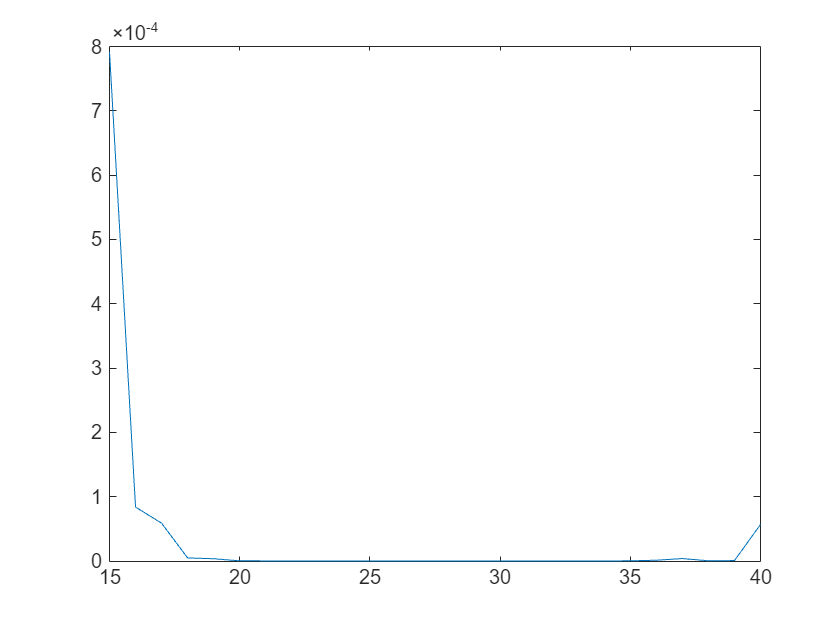

runge(@(x)sin(x), 0, 4*pi, 15:40)

La función seno no presenta fenómeno de Runge. Veamos otra función que sí lo presenta. Primero fijemos un máximo de punto donde aún se recupera el polinomio:

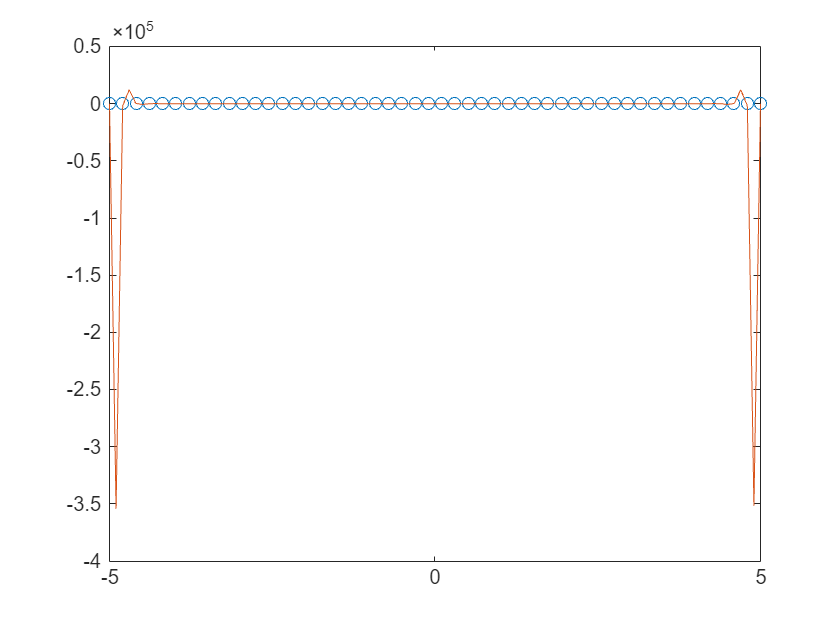

interplot(@(x)1./(1+x.^2), -5, 5, 50);

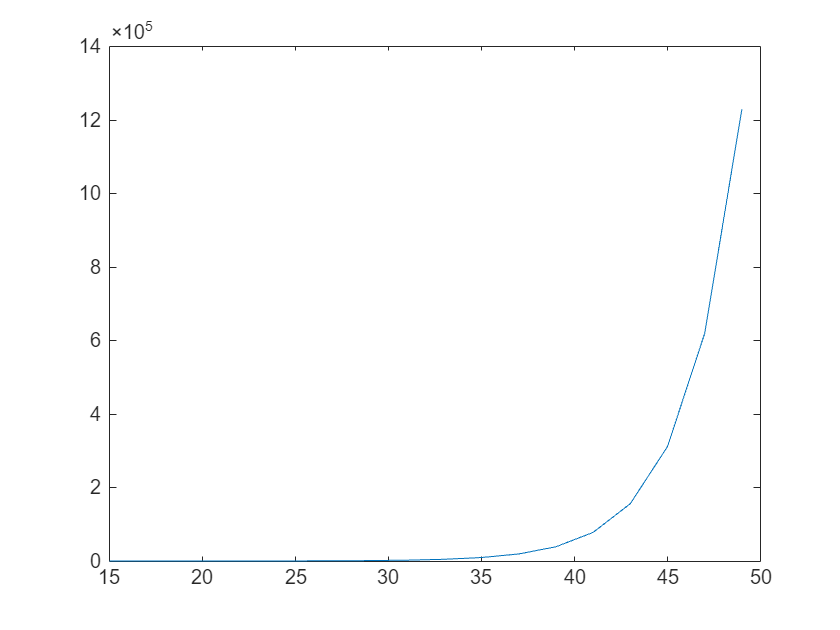

runge(@(x)1./(1+x.^2), -5, 5, 15:2:50)

### Interpolación a trozos

El comando `yp = `[`interp1`](https://es.mathworks.com/help/matlab/ref/interp1.html)`(x, y, xp, method)` permite calcular polinomios de interpolación a trozos mediante varios métodos; entre ellos:

- `'linear'`: interpolación lineal; continuidad en los nodos de la función, no de la derivada. 

- `'spline'`: interpolación por splines cúbicos; continuidad en los nodos de la función y sus derivadas primera y segunda. 

- `'makima'`: interpolación cúbica de Hermite con Akima modificada; continuidad en los nodos de la función y su derivada primera. Genera menos ondulaciones que `'spline' `por lo que es más adecuada allí donde la función es monótona.

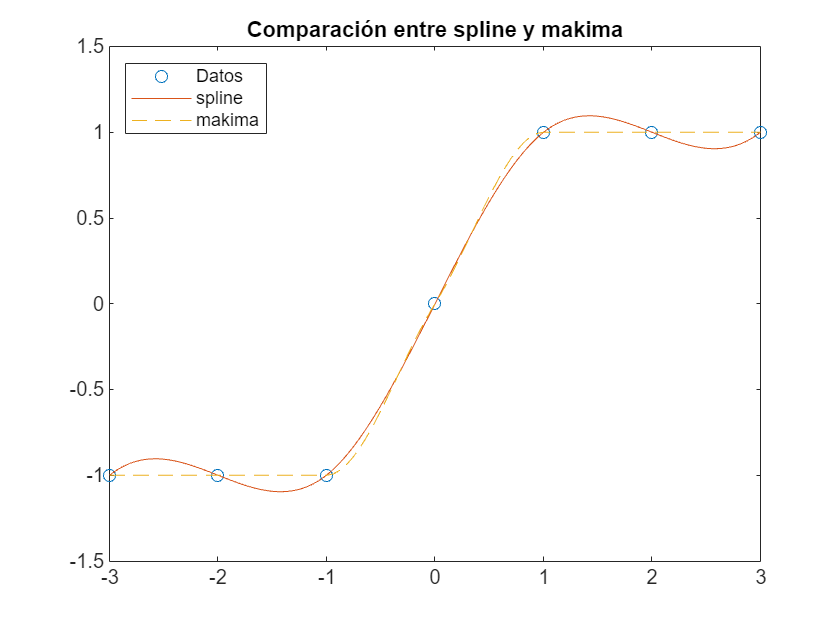

x = -3:3; 
y = [-1 -1 -1 0 1 1 1]; 
xp = linspace(-3,3);
plot(x, y, 'o', xp, interp1(x, y, xp, 'spline'), '-', xp, interp1(x, y, xp, 'makima'), '--')
legend('Datos', 'spline', 'makima','Location','NorthWest')
title('Comparación entre spline y makima')

Si queremos guardar los coeficientes de los polinomios de interpolación a trozos para evaluarlo posteriormente, podemos usar `spline` sin indicar las abcisas de evaluación

x = -3:3; 
y = [-1 -1 -1 0 1 1 1]; 
s = spline(x, y)

s = struct with fields:
      form: 'pp'
    breaks: [-3 -2 -1 0 1 2 3]
     coefs: [6×4 double]
    pieces: 6
     order: 4
       dim: 1


s.coefs

ans =     0.2500   -0.7500    0.5000   -1.0000
    0.2500         0   -0.2500   -1.0000
   -0.2500    0.7500    0.5000   -1.0000
   -0.2500         0    1.2500         0
    0.2500   -0.7500    0.5000    1.0000
    0.2500         0   -0.2500    1.0000


Si queremos obtener una expresión similar para la interpolación por rectas, debemos construir nosotros los coeficientes. Supongamos que aproximamos por rectas esta función:

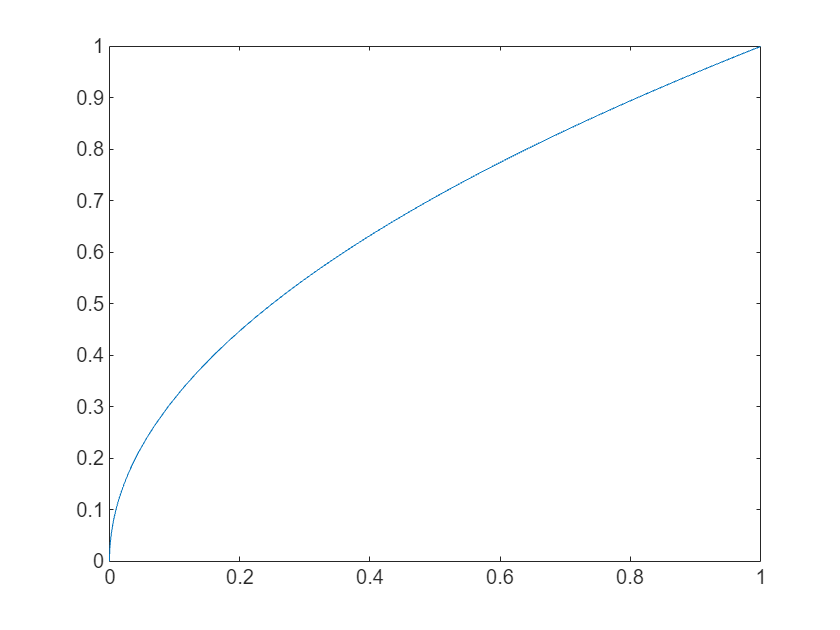

fplot(@sqrt, [0 1])

En `coefs` deben indicarse los coeficientes $a$, $b$ de la recta $y = a(x-x_i)+b$ que pasa por $(x_i, y_i)$ y $(x_{i+1}, y_{i+1})$. Su expresión es $y = \frac{y_{i+1}-y_i}{x_{i+1}-x_i}(x-x_i) + y_i$.

x = linspace(0,1,10); % 10 puntos entre eps y 1
y = sqrt(x);
k = (y(2:end)-y(1:end-1))./(x(2:end)-x(1:end-1));
coefs = [k' y(1:end-1)']

coefs =     3.0000         0
    1.2426    0.3333
    0.9535    0.4714
    0.8038    0.5774
    0.7082    0.6667
    0.6403    0.7454
    0.5888    0.8165
    0.5480    0.8819
    0.5147    0.9428


La función [`mkpp`](https://es.mathworks.com/help/matlab/ref/mkpp.html) genera la estructura del polinomio a trozos:

pp = mkpp(x, coefs)

pp = struct with fields:
      form: 'pp'
    breaks: [0 0.1111 0.2222 0.3333 0.4444 0.5556 0.6667 0.7778 0.8889 1]
     coefs: [9×2 double]
    pieces: 9
     order: 2
       dim: 1


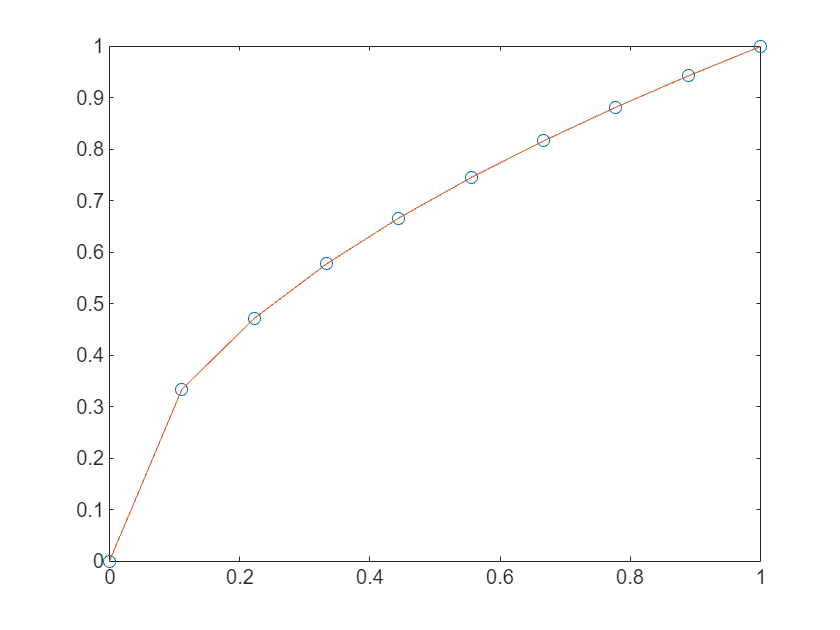

xp = linspace(eps,1);
plot(x,y,'o', xp, ppval(pp, xp))

#### **Ejercicio de modificación de un polinomio de interpolación**

Crea una función que, dada una estructura `pp` como la anterior y un vector de abscisas nuevas, añada dichas abscisas (y las rectas correspondientes) a `pp`. Para encontrar la posición i donde debe añadirse un nuevo elemento  puedes usar la función `inserta`.

v = [1, 3, 5, 7, 9]; % vector ordenado
x = 2;               % nuevo elemento a insertar
p = inserta(v,x)     % indice de insercion

p = 2

if p > 0
    v = [v(p-1) x v(p:end)]
end

v =      1     2     3     5     7     9


Observa que, cuando debas añadir un polinomio en la posición $p$, si $p>1$ debes eliminar el polinomio de la fila $p-1$ de los coeficientes y añadir dos nuevos. Si $p=1$ no debes eliminar ninguno y sólo añadir uno al principio.

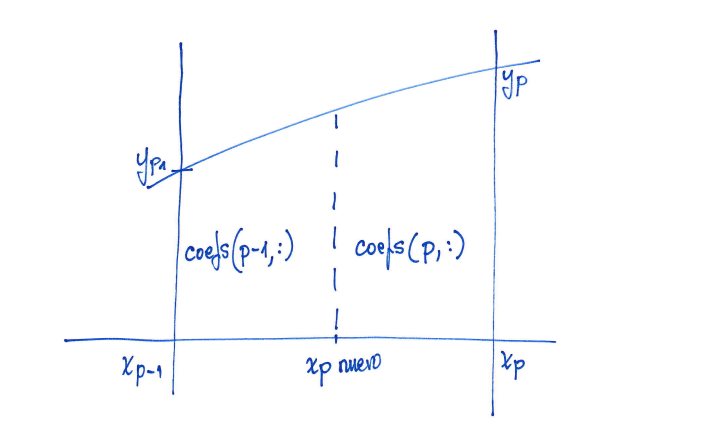

Prueba a añadir 10 abscisas nuevas en el primer intervalo del ejemplo anterior.

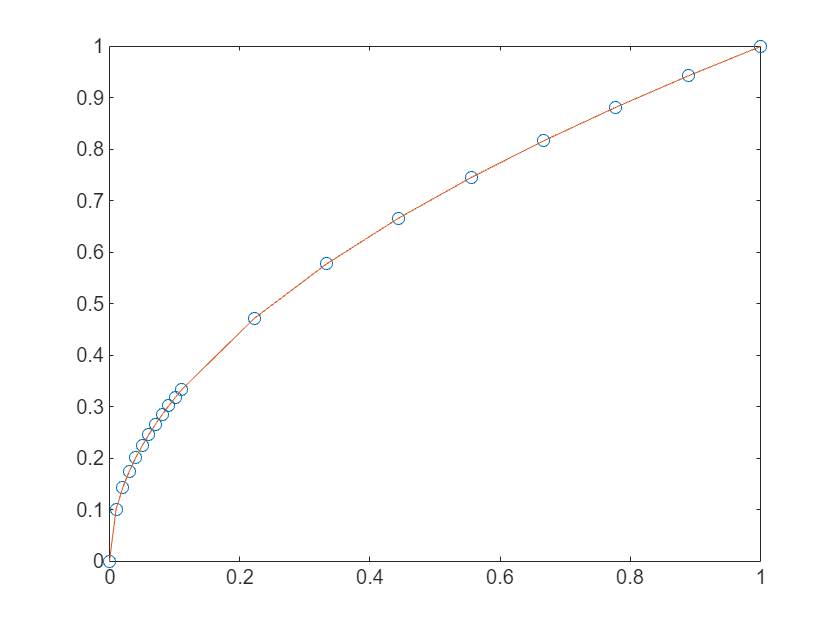

% polinomio original
x = linspace(0,1,10); % 10 puntos entre eps y 1
y = sqrt(x);
k = (y(2:end)-y(1:end-1))./(x(2:end)-x(1:end-1));
coefs = [k' y(1:end-1)'];
pp = mkpp(x, coefs);

%adicion de 10 puntos (11 subintervalos) en el primero
h = (x(2)-x(1))/11;
xn = linspace(x(1)+h, x(2)-h, 10);
yn = sqrt(xn);
addpath('../t5_soluciones')
[x, coefs] = add_pp(pp, xn, yn); %%% POR HACER %%%
pp = mkpp(x, coefs);

%grafica
xp = linspace(0, 1);
plot(pp.breaks,[y(1) yn y(2:end)],'o', xp, ppval(pp, xp))

### Base de Lagrange

Veamos ahora cómo podríamos implementar el cálculo de la base de Lagrange.

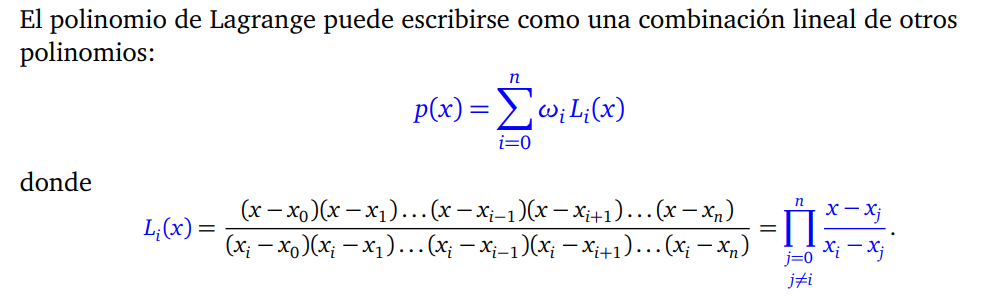

Usaremos la función `poly`, que devuelve el vector de coeficientes del polinomio para unas raíces dadas:

poly([2,3])

ans =      1    -5     6


El cálculo de la base de Lagrange está implementado en la función `lagrange`. Veamos sus propiedades:

x = [1 3 5];
L = lagrange(x);
for i = 1:length(x)
    disp(['Polinomio L(' num2str(i) '): '])
    disp(['  Coeficientes: ' num2str(L(i,:))])
    disp(['  Valor en x:   ' num2str(polyval(L(i,:),x))])
    disp(['  Raíces:       ' num2str(roots(L(i,:))')])
end

Polinomio L(1): 


  Coeficientes: 0.125          -1       1.875


  Valor en x:   1  0  0


  Raíces:       5  3


Polinomio L(2): 


  Coeficientes: -0.25         1.5       -1.25


  Valor en x:   0  1  0


  Raíces:       5  1


Polinomio L(3): 


  Coeficientes: 0.125        -0.5       0.375


  Valor en x:   0  0  1


  Raíces:       3  1


sdas

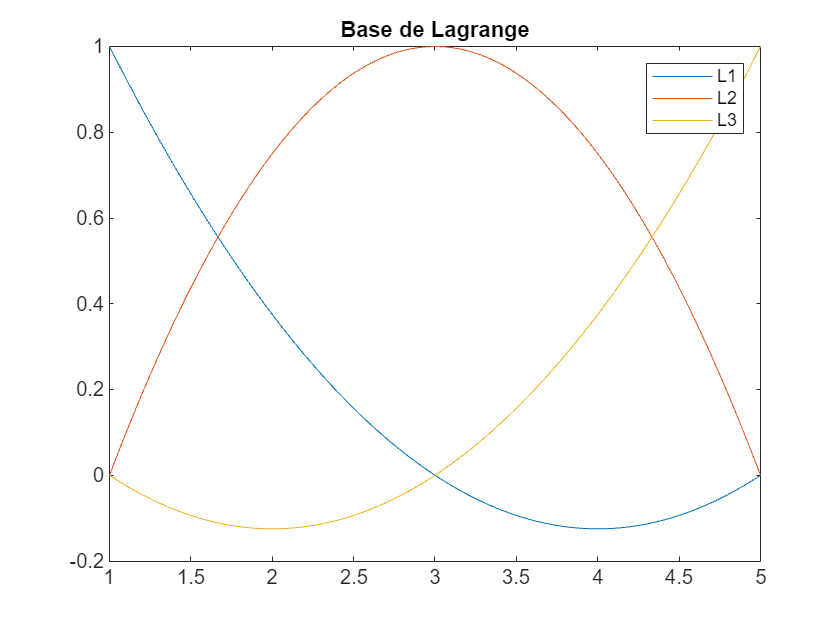

xp = linspace(min(x), max(x)); %por defecto, 100 puntos
Y = zeros(length(x), length(xp));
lgnd = cell(size(x));
for i = 1:length(x)
    Y(i,:) = polyval(L(i,:), xp);
    lgnd{i} = ['L' num2str(i)];
end
plot(xp,Y)
title('Base de Lagrange')
legend(lgnd)

## **Anexo. Funciones locales**

En Matlab, las funciones locales utilizadas en un *script*, van al final de éste.

function p = interplot(f, a, b, n)
    % A documentar 
    x = linspace(a, b, n);
    p = polyfit(x, f(x), length(x)-1);
    xp = linspace(a, b);
    plot(x,f(x),'o', xp, polyval(p,xp))
end

function runge(f, a, b, vn)
    % A documentar 
    xp = linspace(a, b);
    e = zeros(size(vn));
    for i = 1:length(vn)
        x = linspace(a, b, vn(i));
        p = polyfit(x, f(x), length(x)-1);
        e(i) = max(abs(arrayfun(f,xp) - polyval(p, xp)));
    end
    plot(vn, e)
end

function pos = inserta(v, x)
    % A documentar 
    if any(abs(v-x)<eps)
        pos = 0; % no es necesaria la insercion
    else
        pos = find(v >= x, 1);
        if isempty(pos)
            pos = length(v) + 1; % insertar al final
        end
    end
end

function L = lagrange(x)
    % A documentar
    L = zeros(size(x));
    for i = 1:length(x)
        L(i,:) = poly(x([1:i-1 i+1:end]))/prod(x(i) - x([1:i-1 i+1:end]));
    end
end